# Análisis motores y reductores biela-manivela

## Selección reductor

#### Cinemática eje

clear

TCA1iz=readtable("MatLab cinematica\docTXT\ArfadaCaso1iz.txt");
TCA2iz=readtable("MatLab cinematica\docTXT\ArfadaCaso2iz.txt");
TCA3iz=readtable("MatLab cinematica\docTXT\ArfadaCaso3iz.txt");
TCC1iz=readtable("MatLab cinematica\docTXT\CabeceoCaso1iz.txt");
TCC2iz=readtable("MatLab cinematica\docTXT\CabeceoCaso2iz.txt");
TCC3iz=readtable("MatLab cinematica\docTXT\CabeceoCaso3iz.txt");
TCB1iz=readtable("MatLab cinematica\docTXT\BalanceoCaso1iz.txt");
TCB2iz=readtable("MatLab cinematica\docTXT\BalanceoCaso2iz.txt");
TCB3iz=readtable("MatLab cinematica\docTXT\BalanceoCaso3iz.txt");

TCA1de=readtable("MatLab cinematica\docTXT\ArfadaCaso1de.txt");
TCA2de=readtable("MatLab cinematica\docTXT\ArfadaCaso2de.txt");
TCA3de=readtable("MatLab cinematica\docTXT\ArfadaCaso3de.txt");
TCC1de=readtable("MatLab cinematica\docTXT\CabeceoCaso1de.txt");
TCC2de=readtable("MatLab cinematica\docTXT\CabeceoCaso2de.txt");
TCC3de=readtable("MatLab cinematica\docTXT\CabeceoCaso3de.txt");
TCB1de=readtable("MatLab cinematica\docTXT\BalanceoCaso1de.txt");
TCB2de=readtable("MatLab cinematica\docTXT\BalanceoCaso2de.txt");
TCB3de=readtable("MatLab cinematica\docTXT\BalanceoCaso3de.txt");


tMax_a=(10*sqrt(sym(1090)))/327

$$tMax\_a = \frac{10\,\sqrt{1090}}{327}$$

tMax_b=(sqrt(sym(6))*sqrt(sym(pi)))/3

$$tMax\_b = \frac{\sqrt{6}\,\sqrt{\pi }}{3}$$

tMax_c=(sqrt(sym(17))*sqrt(sym(pi)))/3

$$tMax\_c = \frac{\sqrt{17}\,\sqrt{\pi }}{3}$$

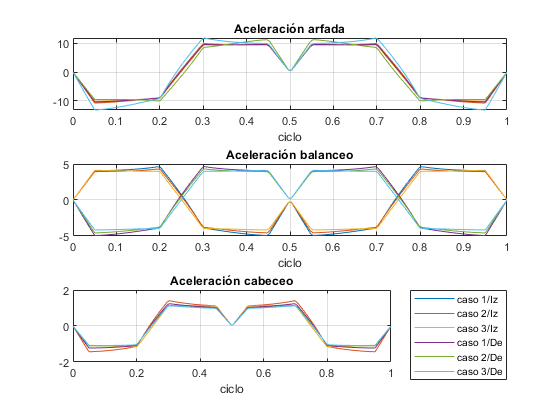





aceleracionA1iz=TCA1iz.AceleracionAngularArfada;
aceleracionA2iz=TCA2iz.AceleracionAngularArfada;
aceleracionA3iz=TCA3iz.AceleracionAngularArfada;
aceleracionC1iz=TCC1iz.AceleracionAngularCabeceo;
aceleracionC2iz=TCC2iz.AceleracionAngularCabeceo;
aceleracionC3iz=TCC3iz.AceleracionAngularCabeceo;
aceleracionB1iz=TCB1iz.AceleracionAngularBalanceo;
aceleracionB2iz=TCB2iz.AceleracionAngularBalanceo;
aceleracionB3iz=TCB3iz.AceleracionAngularBalanceo;
aceleracionA1de=TCA1de.AceleracionAngularArfada;
aceleracionA2de=TCA2de.AceleracionAngularArfada;
aceleracionA3de=TCA3de.AceleracionAngularArfada;
aceleracionC1de=TCC1de.AceleracionAngularCabeceo;
aceleracionC2de=TCC2de.AceleracionAngularCabeceo;
aceleracionC3de=TCC3de.AceleracionAngularCabeceo;
aceleracionB1de=TCB1de.AceleracionAngularBalanceo;
aceleracionB2de=TCB2de.AceleracionAngularBalanceo;
aceleracionB3de=TCB3de.AceleracionAngularBalanceo;
figure()
subplot(3,1,1)
plot(linspace(0,1,160),aceleracionA1iz)
hold on
plot(linspace(0,1,160),aceleracionA2iz)
plot(linspace(0,1,160),aceleracionA3iz)
plot(linspace(0,1,160),aceleracionA1de)
plot(linspace(0,1,160),aceleracionA2de)
plot(linspace(0,1,160),aceleracionA3de)
hold off
xlabel("ciclo")
%legend("caso 1/Iz","caso 2/Iz","caso 3/Iz","caso 1/De","caso 2/De","caso 3/De","Location","bestoutside")
title("Aceleración arfada")
grid on
subplot(3,1,2)
plot(linspace(0,1,160),aceleracionB1iz)
hold on
plot(linspace(0,1,160),aceleracionB2iz)
plot(linspace(0,1,160),aceleracionB3iz)
plot(linspace(0,1,160),aceleracionB1de)
plot(linspace(0,1,160),aceleracionB2de)
plot(linspace(0,1,160),aceleracionB3de)
hold off
xlabel("ciclo")
%legend("caso 1/Iz","caso 2/Iz","caso 3/Iz","caso 1/De","caso 2/De","caso 3/De","Location","bestoutside")
title("Aceleración balanceo")
grid on
subplot(3,1,3)
plot(linspace(0,1,160),aceleracionC1iz)
hold on
plot(linspace(0,1,160),aceleracionC2iz)
plot(linspace(0,1,160),aceleracionC3iz)
plot(linspace(0,1,160),aceleracionC1de)
plot(linspace(0,1,160),aceleracionC2de)
plot(linspace(0,1,160),aceleracionC3de)
hold off
xlabel("ciclo")
legend("caso 1/Iz","caso 2/Iz","caso 3/Iz","caso 1/De","caso 2/De","caso 3/De","Location","bestoutside")
title("Aceleración cabeceo")
grid on

#### Torques eje

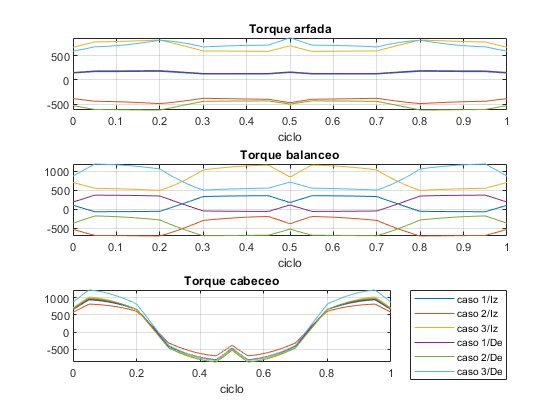

TTA1iz=readtable("MatLab cinetica\Torques\MIArfadaC1.txt");
TTA2iz=readtable("MatLab cinetica\Torques\MIArfadaC2.txt");
TTA3iz=readtable("MatLab cinetica\Torques\MIArfadaC3.txt");
TTC1iz=readtable("MatLab cinetica\Torques\MICabeceoC1.txt");
TTC2iz=readtable("MatLab cinetica\Torques\MICabeceoC2.txt");
TTC3iz=readtable("MatLab cinetica\Torques\MICabeceoC3.txt");
TTB1iz=readtable("MatLab cinetica\Torques\MIBalanceoC1.txt");
TTB2iz=readtable("MatLab cinetica\Torques\MIBalanceoC2.txt");
TTB3iz=readtable("MatLab cinetica\Torques\MIBalanceoC3.txt");

TTA1de=readtable("MatLab cinetica\Torques\MDArfadaC1.txt");
TTA2de=readtable("MatLab cinetica\Torques\MDArfadaC2.txt");
TTA3de=readtable("MatLab cinetica\Torques\MDArfadaC3.txt");
TTC1de=readtable("MatLab cinetica\Torques\MDCabeceoC1.txt");
TTC2de=readtable("MatLab cinetica\Torques\MDCabeceoC2.txt");
TTC3de=readtable("MatLab cinetica\Torques\MDCabeceoC3.txt");
TTB1de=readtable("MatLab cinetica\Torques\MDBalanceoC1.txt");
TTB2de=readtable("MatLab cinetica\Torques\MDBalanceoC2.txt");
TTB3de=readtable("MatLab cinetica\Torques\MDBalanceoC3.txt");

TorqueA1iz=TTA1iz.Var2/1000;
TorqueA2iz=TTA2iz.Var2/1000;
TorqueA3iz=TTA3iz.Var2/1000;
TorqueC1iz=TTC1iz.Var2/1000;
TorqueC2iz=TTC2iz.Var2/1000;
TorqueC3iz=TTC3iz.Var2/1000;
TorqueB1iz=TTB1iz.Var2/1000;
TorqueB2iz=TTB2iz.Var2/1000;
TorqueB3iz=TTB3iz.Var2/1000;

TorqueA1de=TTA1de.Var2/1000;
TorqueA2de=TTA2de.Var2/1000;
TorqueA3de=TTA3de.Var2/1000;
TorqueC1de=TTC1de.Var2/1000;
TorqueC2de=TTC2de.Var2/1000;
TorqueC3de=TTC3de.Var2/1000;
TorqueB1de=TTB1de.Var2/1000;
TorqueB2de=TTB2de.Var2/1000;
TorqueB3de=TTB3de.Var2/1000;
figure()
subplot(3,1,1)
plot(linspace(0,1,160),TorqueA1iz)
hold on
plot(linspace(0,1,160),TorqueA2iz)
plot(linspace(0,1,160),TorqueA3iz)
plot(linspace(0,1,160),TorqueA1de)
plot(linspace(0,1,160),TorqueA2de)
plot(linspace(0,1,160),TorqueA3de)
hold off
grid on
%legend("caso 1/Iz","caso 2/Iz","caso 3/Iz","caso 1/De","caso 2/De","caso 3/De","Location","bestoutside")
title("Torque arfada")
xlabel("ciclo")
subplot(3,1,2)
plot(linspace(0,1,160),TorqueB1iz)
hold on
plot(linspace(0,1,160),TorqueB2iz)
plot(linspace(0,1,160),TorqueB3iz)
plot(linspace(0,1,160),TorqueB1de)
plot(linspace(0,1,160),TorqueB2de)
plot(linspace(0,1,160),TorqueB3de)
hold off
grid on
%legend("caso 1/Iz","caso 2/Iz","caso 3/Iz","caso 1/De","caso 2/De","caso 3/De","Location","bestoutside")
title("Torque balanceo")
xlabel("ciclo")
subplot(3,1,3)
plot(linspace(0,1,160),TorqueC1iz)
hold on
plot(linspace(0,1,160),TorqueC2iz)
plot(linspace(0,1,160),TorqueC3iz)
plot(linspace(0,1,160),TorqueC1de)
plot(linspace(0,1,160),TorqueC2de)
plot(linspace(0,1,160),TorqueC3de)
hold off
grid on
legend("caso 1/Iz","caso 2/Iz","caso 3/Iz","caso 1/De","caso 2/De","caso 3/De","Location","bestoutside")
title("Torque cabeceo")
xlabel("ciclo")

#### Inercia total

IncerciaAparenteA1iz=abs(TorqueA1iz./aceleracionA1iz);
IncerciaAparenteA2iz=abs(TorqueA2iz./aceleracionA2iz);
IncerciaAparenteA3iz=abs(TorqueA3iz./aceleracionA3iz);
IncerciaAparenteC1iz=abs(TorqueC1iz./aceleracionC1iz);
IncerciaAparenteC2iz=abs(TorqueC2iz./aceleracionC2iz);
IncerciaAparenteC3iz=abs(TorqueC3iz./aceleracionC3iz);
IncerciaAparenteB1iz=abs(TorqueB1iz./aceleracionB1iz);
IncerciaAparenteB2iz=abs(TorqueB2iz./aceleracionB2iz);
IncerciaAparenteB3iz=abs(TorqueB3iz./aceleracionB3iz);

IncerciaAparenteA1de=abs(TorqueA1de./aceleracionA1de);
IncerciaAparenteA2de=abs(TorqueA2de./aceleracionA2de);
IncerciaAparenteA3de=abs(TorqueA3de./aceleracionA3de);
IncerciaAparenteC1de=abs(TorqueC1de./aceleracionC1de);
IncerciaAparenteC2de=abs(TorqueC2de./aceleracionC2de);
IncerciaAparenteC3de=abs(TorqueC3de./aceleracionC3de);
IncerciaAparenteB1de=abs(TorqueB1de./aceleracionB1de);
IncerciaAparenteB2de=abs(TorqueB2de./aceleracionB2de);
IncerciaAparenteB3de=abs(TorqueB3de./aceleracionB3de);

IncerciaAparenteA1iz(abs(aceleracionA1iz)<0.2)=[];
IncerciaAparenteA2iz(abs(aceleracionA2iz)<0.2)=[];
IncerciaAparenteA3iz(abs(aceleracionA3iz)<0.2)=[];
IncerciaAparenteC1iz(abs(aceleracionC1iz)<0.2)=[];
IncerciaAparenteC2iz(abs(aceleracionC2iz)<0.2)=[];
IncerciaAparenteC3iz(abs(aceleracionC3iz)<0.2)=[];
IncerciaAparenteB1iz(abs(aceleracionB1iz)<0.2)=[];
IncerciaAparenteB2iz(abs(aceleracionB2iz)<0.2)=[];
IncerciaAparenteB3iz(abs(aceleracionB3iz)<0.2)=[];

IncerciaAparenteA1de(abs(aceleracionA1de)<0.2)=[];
IncerciaAparenteA2de(abs(aceleracionA2de)<0.2)=[];
IncerciaAparenteA3de(abs(aceleracionA3de)<0.2)=[];
IncerciaAparenteC1de(abs(aceleracionC1de)<0.2)=[];
IncerciaAparenteC2de(abs(aceleracionC2de)<0.2)=[];
IncerciaAparenteC3de(abs(aceleracionC3de)<0.2)=[];
IncerciaAparenteB1de(abs(aceleracionB1de)<0.2)=[];
IncerciaAparenteB2de(abs(aceleracionB2de)<0.2)=[];
IncerciaAparenteB3de(abs(aceleracionB3de)<0.2)=[];


%Arfada

tiempoArfada=linspace(0,double(tMax_a),160);
TA1iz=tiempoArfada;
TA1iz(abs(aceleracionA1iz)<0.2)=[];
TA2iz=tiempoArfada;
TA2iz(abs(aceleracionA2iz)<0.2)=[];
TA3iz=tiempoArfada;
TA3iz(abs(aceleracionA3iz)<0.2)=[];


figure()
plot(TA1iz,IncerciaAparenteA1iz,TA2iz,IncerciaAparenteA2iz,TA3iz,IncerciaAparenteA3iz)
legend("Caso 1","Caso 2","Caso 3","location","best")
title("Inercia arfada reductor izquierdo")
grid on
xlim([0 double(tMax_a)])
xlabel("Tiempo (s)")

matInArfIz=[IncerciaAparenteA1iz;IncerciaAparenteA2iz;IncerciaAparenteA3iz];
Vmax=max(matInArfIz);
disp("Valor máximo: "+Vmax+" kg m^2")

Valor máximo: 1294.485 kg m^2


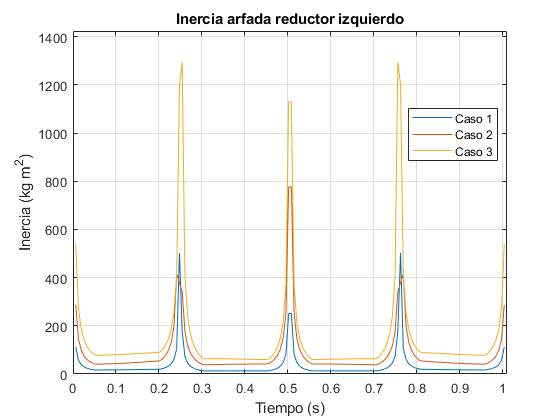

ylim([0 Vmax*1.1])
ylabel("Inercia (kg m^2)")

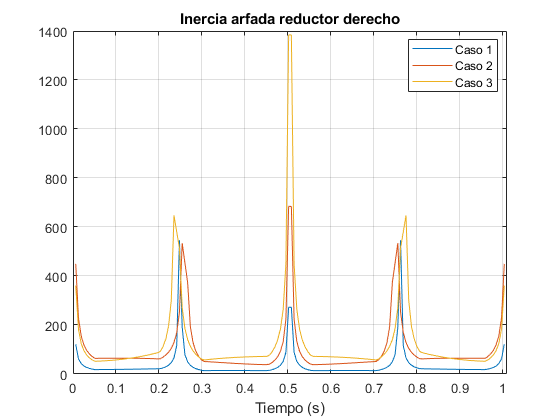

ArregloInerciaMaxima(1)=Vmax;

TA1de=tiempoArfada;
TA1de(abs(aceleracionA1de)<0.2)=[];
TA2de=tiempoArfada;
TA2de(abs(aceleracionA2de)<0.2)=[];
TA3de=tiempoArfada;
TA3de(abs(aceleracionA3de)<0.2)=[];


figure()
plot(TA1de,IncerciaAparenteA1de,TA2de,IncerciaAparenteA2de,TA3de,IncerciaAparenteA3de)
legend("Caso 1","Caso 2","Caso 3","location","best")
title("Inercia arfada reductor derecho")
grid on
xlim([0 double(tMax_a)])
xlabel("Tiempo (s)")




matInArfDe=[IncerciaAparenteA1de;IncerciaAparenteA2de;IncerciaAparenteA3de];

Vmax=max(matInArfDe);

disp("Valor máximo: "+Vmax+" kg m^2")

Valor máximo: 1383.9502 kg m^2


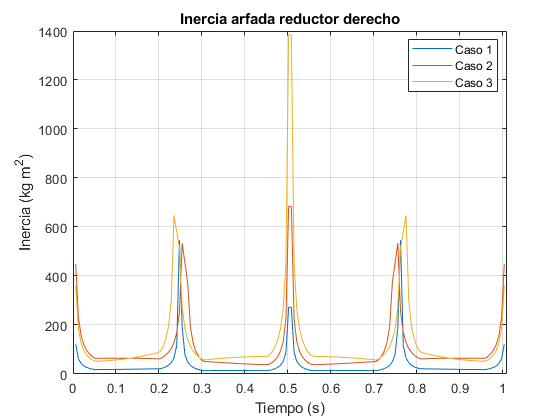

ylabel("Inercia (kg m^2)")

ArregloInerciaMaxima(2)=Vmax;
%Cabeceo
tiempoCabeceo=linspace(0,double(tMax_c),160);

TC1iz=tiempoCabeceo;
TC1iz(abs(aceleracionC1iz)<0.2)=[];
TC2iz=tiempoCabeceo;
TC2iz(abs(aceleracionC2iz)<0.2)=[];
TC3iz=tiempoCabeceo;
TC3iz(abs(aceleracionC3iz)<0.2)=[];

figure()
plot(TC1iz,IncerciaAparenteC1iz,TC2iz,IncerciaAparenteC2iz,TC3iz,IncerciaAparenteC3iz)
legend("Caso 1","Caso 2","Caso 3","location","best")
title("Inercia cabeceo reductor izquierdo")
grid on
xlim([0 double(tMax_c)])
xlabel("Tiempo (s)")

matInCabIz=[IncerciaAparenteC1iz;IncerciaAparenteC2iz;IncerciaAparenteC3iz];
Vmax=max(matInCabIz);
disp("Valor máximo: "+Vmax+" kg m^2")

Valor máximo: 2918.8673 kg m^2


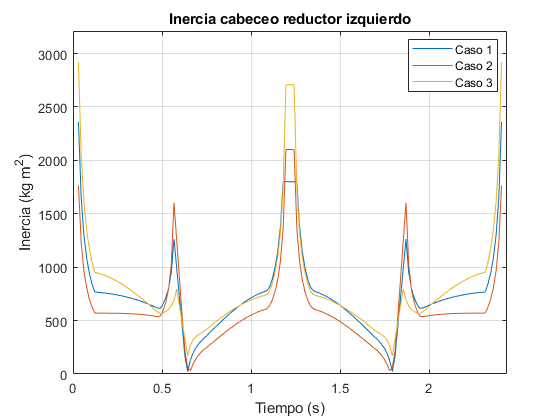

ylim([0 Vmax*1.1])
ylabel("Inercia (kg m^2)")

ArregloInerciaMaxima(3)=Vmax;

TC1de=tiempoCabeceo;
TC1de(abs(aceleracionC1de)<0.2)=[];
TC2de=tiempoCabeceo;
TC2de(abs(aceleracionC2de)<0.2)=[];
TC3de=tiempoCabeceo;
TC3de(abs(aceleracionC3de)<0.2)=[];

figure()
plot(TC1de,IncerciaAparenteC1de,TC2de,IncerciaAparenteC2de,TC3de,IncerciaAparenteC3de)
legend("Caso 1","Caso 2","Caso 3","location","best")
title("Inercia cabeceo reductor derecho")
grid on
xlim([0 double(tMax_c)])
xlabel("Tiempo (s)")

matInCabDe=[IncerciaAparenteC1de;IncerciaAparenteC2de;IncerciaAparenteC3de];
Vmax=max(matInCabDe);
disp("Valor máximo: "+Vmax+" kg m^2")

Valor máximo: 3538.2804 kg m^2


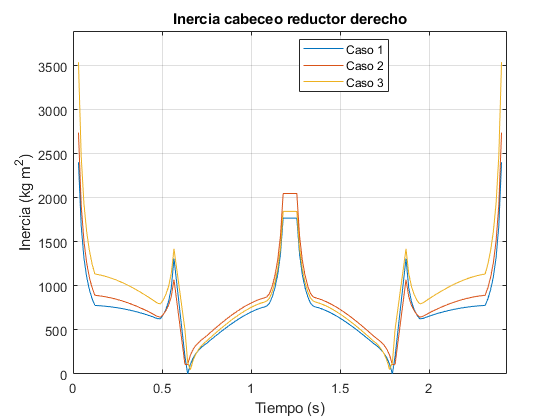

ylim([0 Vmax*1.1])
ylabel("Inercia (kg m^2)")

ArregloInerciaMaxima(4)=Vmax;

%Balanceo
tiempoBalanceo=linspace(0,double(tMax_b),160);
TB1iz=tiempoBalanceo;
TB1iz(abs(aceleracionB1iz)<0.2)=[];
TB2iz=tiempoBalanceo;
TB2iz(abs(aceleracionB2iz)<0.2)=[];
TB3iz=tiempoBalanceo;
TB3iz(abs(aceleracionB3iz)<0.2)=[];

figure()
plot(TB1iz,IncerciaAparenteB1iz,TB2iz,IncerciaAparenteB2iz,TB3iz,IncerciaAparenteB3iz)
legend("Caso 1","Caso 2","Caso 3","location","best")
title("Inercia balanceo reductor izquierdo")
grid on
xlim([0 double(tMax_b)])
xlabel("Tiempo (s)")

matInBalDe=[IncerciaAparenteB1iz;IncerciaAparenteB2iz;IncerciaAparenteB3iz];
Vmax=max(matInBalDe);
disp("Valor máximo: "+Vmax+" kg m^2")

Valor máximo: 3282.9524 kg m^2


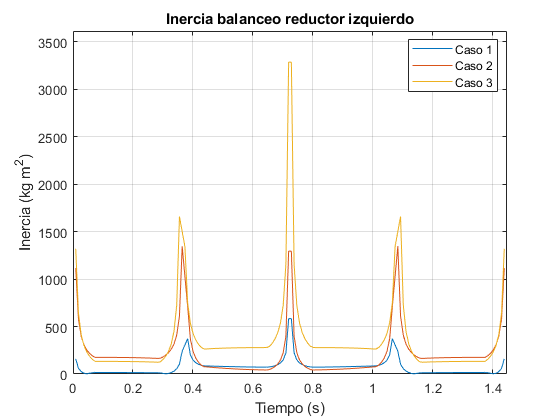

ylim([0 Vmax*1.1])
ylabel("Inercia (kg m^2)")

ArregloInerciaMaxima(5)=Vmax;

TB1de=tiempoBalanceo;
TB1de(abs(aceleracionB1de)<0.2)=[];
TB2de=tiempoBalanceo;
TB2de(abs(aceleracionB2de)<0.2)=[];
TB3de=tiempoBalanceo;
TB3de(abs(aceleracionB3de)<0.2)=[];

figure()
plot(TB1de,IncerciaAparenteB1de,TB2de,IncerciaAparenteB2de,TB3de,IncerciaAparenteB3de)
legend("Caso 1","Caso 2","Caso 3","location","best")
title("Inercia balanceo reductor derecho")
grid on
xlim([0 double(tMax_b)])
xlabel("Tiempo (s)")

matInBalDe=[IncerciaAparenteB1de;IncerciaAparenteB2de;IncerciaAparenteB3de];
Vmax=max(matInBalDe);
disp("Valor máximo: "+Vmax+" kg m^2")

Valor máximo: 2722.7359 kg m^2


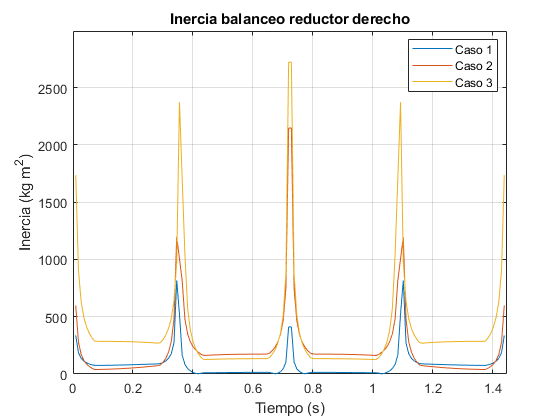

ylim([0 Vmax*1.1])
ylabel("Inercia (kg m^2)")

ArregloInerciaMaxima(6)=Vmax;

InerciaMaxima=max(ArregloInerciaMaxima);
disp("Inercia máxima del sistema: "+InerciaMaxima+" kg m^2")

Inercia máxima del sistema: 3538.2804 kg m^2


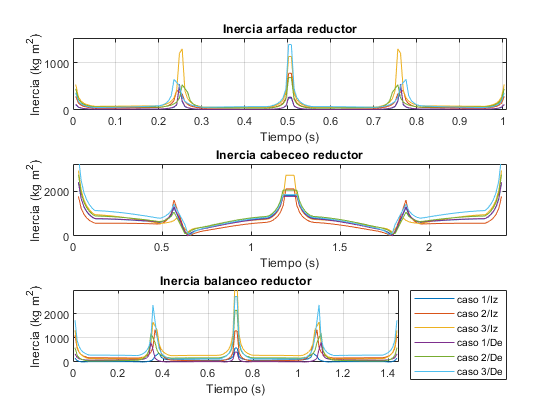



figure()
subplot(3,1,1)
plot(TA1iz,IncerciaAparenteA1iz,TA2iz,IncerciaAparenteA2iz,TA3iz,IncerciaAparenteA3iz,TA1de,IncerciaAparenteA1de,TA2de,IncerciaAparenteA2de,TA3de,IncerciaAparenteA3de)
xlim([0 double(tMax_a)])
grid on
xlabel("Tiempo (s)")
ylabel("Inercia (kg m^2)")
title("Inercia arfada reductor")
ylim([0 ArregloInerciaMaxima(2)*1.1])
subplot(3,1,2)
plot(TC1iz,IncerciaAparenteC1iz,TC2iz,IncerciaAparenteC2iz,TC3iz,IncerciaAparenteC3iz,TC1de,IncerciaAparenteC1de,TC2de,IncerciaAparenteC2de,TC3de,IncerciaAparenteC3de)
xlim([0 double(tMax_c)])
grid on
xlabel("Tiempo (s)")
ylabel("Inercia (kg m^2)")
title("Inercia cabeceo reductor")
ylim([0 ArregloInerciaMaxima(3)*1.1])
subplot(3,1,3)
plot(TB1iz,IncerciaAparenteB1iz,TB2iz,IncerciaAparenteB2iz,TB3iz,IncerciaAparenteB3iz,TB1de,IncerciaAparenteB1de,TB2de,IncerciaAparenteB2de,TB3de,IncerciaAparenteB3de)
xlim([0 double(tMax_b)])
grid on
xlabel("Tiempo (s)")
ylabel("Inercia (kg m^2)")
title("Inercia balanceo reductor")
ylim([0 ArregloInerciaMaxima(6)*1.1])
legend("caso 1/Iz","caso 2/Iz","caso 3/Iz","caso 1/De","caso 2/De","caso 3/De","Location","bestoutside")

### Velocidad salida

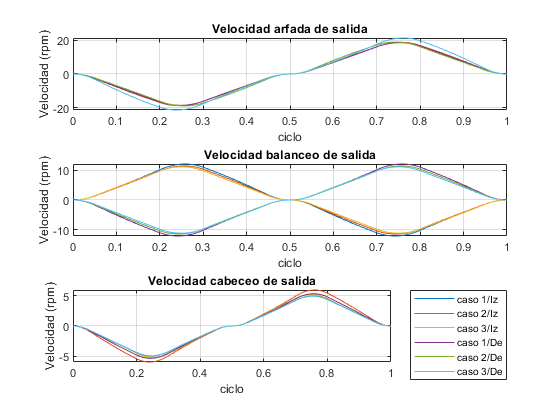

velocidadA1iz=TCA1iz.VelocidadAngularArfada;
velocidadA2iz=TCA2iz.VelocidadAngularArfada;
velocidadA3iz=TCA3iz.VelocidadAngularArfada;
velocidadC1iz=TCC1iz.VelocidadAngularCabeceo;
velocidadC2iz=TCC2iz.VelocidadAngularCabeceo;
velocidadC3iz=TCC3iz.VelocidadAngularCabeceo;
velocidadB1iz=TCB1iz.VelocidadAngularBalanceo;
velocidadB2iz=TCB2iz.VelocidadAngularBalanceo;
velocidadB3iz=TCB3iz.VelocidadAngularBalanceo;
velocidadA1de=TCA1de.VelocidadAngularArfada;
velocidadA2de=TCA2de.VelocidadAngularArfada;
velocidadA3de=TCA3de.VelocidadAngularArfada;
velocidadC1de=TCC1de.VelocidadAngularCabeceo;
velocidadC2de=TCC2de.VelocidadAngularCabeceo;
velocidadC3de=TCC3de.VelocidadAngularCabeceo;
velocidadB1de=TCB1de.VelocidadAngularBalanceo;
velocidadB2de=TCB2de.VelocidadAngularBalanceo;
velocidadB3de=TCB3de.VelocidadAngularBalanceo;


figure()
subplot(3,1,1)
plot(linspace(0,1,160),velocidadA1iz*30/pi)
hold on
plot(linspace(0,1,160),velocidadA2iz*30/pi)
plot(linspace(0,1,160),velocidadA3iz*30/pi)
plot(linspace(0,1,160),velocidadA1de*30/pi)
plot(linspace(0,1,160),velocidadA2de*30/pi)
plot(linspace(0,1,160),velocidadA3de*30/pi)
hold off
%legend("caso 1/Iz","caso 2/Iz","caso 3/Iz","caso 1/De","caso 2/De","caso 3/De","Location","bestoutside")
title("Velocidad arfada de salida")
ylabel("Velocidad (rpm)")
xlabel("ciclo")
grid on
subplot(3,1,2)
plot(linspace(0,1,160),velocidadB1iz*30/pi)
hold on
plot(linspace(0,1,160),velocidadB2iz*30/pi)
plot(linspace(0,1,160),velocidadB3iz*30/pi)
plot(linspace(0,1,160),velocidadB1de*30/pi)
plot(linspace(0,1,160),velocidadB2de*30/pi)
plot(linspace(0,1,160),velocidadB3de*30/pi)
hold off
%legend("caso 1/Iz","caso 2/Iz","caso 3/Iz","caso 1/De","caso 2/De","caso 3/De","Location","bestoutside")
title("Velocidad balanceo de salida")
ylabel("Velocidad (rpm)")
xlabel("ciclo")
grid on
subplot(3,1,3)
plot(linspace(0,1,160),velocidadC1iz*30/pi)
hold on
plot(linspace(0,1,160),velocidadC2iz*30/pi)
plot(linspace(0,1,160),velocidadC3iz*30/pi)
plot(linspace(0,1,160),velocidadC1de*30/pi)
plot(linspace(0,1,160),velocidadC2de*30/pi)
plot(linspace(0,1,160),velocidadC3de*30/pi)
hold off
legend("caso 1/Iz","caso 2/Iz","caso 3/Iz","caso 1/De","caso 2/De","caso 3/De","Location","bestoutside")
title("Velocidad cabeceo de salida")
ylabel("Velocidad (rpm)")
xlabel("ciclo")
grid on

### Potencia máquina

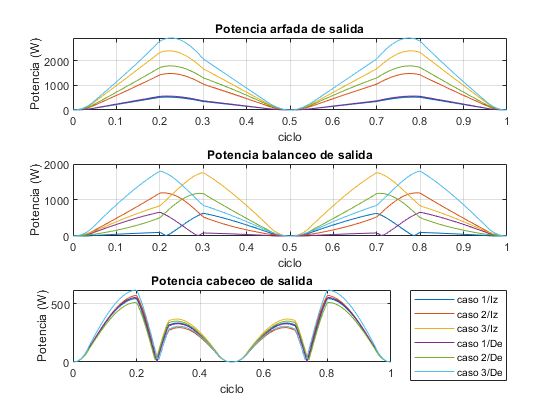

FactorServicio=1.65; %12 horas diarias, carga tipo 3


PotenciaA1iz=abs(TorqueA1iz.*velocidadA1iz)*FactorServicio;
PotenciaA2iz=abs(TorqueA2iz.*velocidadA2iz)*FactorServicio;
PotenciaA3iz=abs(TorqueA3iz.*velocidadA3iz)*FactorServicio;
PotenciaC1iz=abs(TorqueC1iz.*velocidadC1iz)*FactorServicio;
PotenciaC2iz=abs(TorqueC2iz.*velocidadC2iz)*FactorServicio;
PotenciaC3iz=abs(TorqueC3iz.*velocidadC3iz)*FactorServicio;
PotenciaB1iz=abs(TorqueB1iz.*velocidadB1iz)*FactorServicio;
PotenciaB2iz=abs(TorqueB2iz.*velocidadB2iz)*FactorServicio;
PotenciaB3iz=abs(TorqueB3iz.*velocidadB3iz)*FactorServicio;

PotenciaA1de=abs(TorqueA1de.*velocidadA1de)*FactorServicio;
PotenciaA2de=abs(TorqueA2de.*velocidadA2de)*FactorServicio;
PotenciaA3de=abs(TorqueA3de.*velocidadA3de)*FactorServicio;
PotenciaC1de=abs(TorqueC1de.*velocidadC1de)*FactorServicio;
PotenciaC2de=abs(TorqueC2de.*velocidadC2de)*FactorServicio;
PotenciaC3de=abs(TorqueC3de.*velocidadC3de)*FactorServicio;
PotenciaB1de=abs(TorqueB1de.*velocidadB1de)*FactorServicio;
PotenciaB2de=abs(TorqueB2de.*velocidadB2de)*FactorServicio;
PotenciaB3de=abs(TorqueB3de.*velocidadB3de)*FactorServicio;

TablaPotenciaSalida=table(PotenciaA1iz,PotenciaA2iz,PotenciaA3iz,PotenciaC1iz,PotenciaC2iz,PotenciaC3iz,PotenciaB1iz,PotenciaB2iz,PotenciaB3iz,PotenciaA1de,PotenciaA2de,PotenciaA3de,PotenciaC1de,PotenciaC2de,PotenciaC3de,PotenciaB1de,PotenciaB2de,PotenciaB3de);

PRMSPotenciaA1iz=rms(PotenciaA1iz);
PRMSPotenciaA2iz=rms(PotenciaA2iz);
PRMSPotenciaA3iz=rms(PotenciaA3iz);
PRMSPotenciaC1iz=rms(PotenciaC1iz);
PRMSPotenciaC2iz=rms(PotenciaC2iz);
PRMSPotenciaC3iz=rms(PotenciaC3iz);
PRMSPotenciaB1iz=rms(PotenciaB1iz);
PRMSPotenciaB2iz=rms(PotenciaB2iz);
PRMSPotenciaB3iz=rms(PotenciaB3iz);

PRMSPotenciaA1de=rms(PotenciaA1de);
PRMSPotenciaA2de=rms(PotenciaA2de);
PRMSPotenciaA3de=rms(PotenciaA3de);
PRMSPotenciaC1de=rms(PotenciaC1de);
PRMSPotenciaC2de=rms(PotenciaC2de);
PRMSPotenciaC3de=rms(PotenciaC3de);
PRMSPotenciaB1de=rms(PotenciaB1de);
PRMSPotenciaB2de=rms(PotenciaB2de);
PRMSPotenciaB3de=rms(PotenciaB3de);

figure()
subplot(3,1,1)
plot(linspace(0,1,160),PotenciaA1iz)
hold on
plot(linspace(0,1,160),PotenciaA2iz)
plot(linspace(0,1,160),PotenciaA3iz)
plot(linspace(0,1,160),PotenciaA1de)
plot(linspace(0,1,160),PotenciaA2de)
plot(linspace(0,1,160),PotenciaA3de)
hold off
%legend("caso 1/Iz","caso 2/Iz","caso 3/Iz","caso 1/De","caso 2/De","caso 3/De","Location","bestoutside")
title("Potencia arfada de salida")
ylabel("Potencia (W)")
xlabel("ciclo")
grid on
subplot(3,1,2)
plot(linspace(0,1,160),PotenciaB1iz)
hold on
plot(linspace(0,1,160),PotenciaB2iz)
plot(linspace(0,1,160),PotenciaB3iz)
plot(linspace(0,1,160),PotenciaB1de)
plot(linspace(0,1,160),PotenciaB2de)
plot(linspace(0,1,160),PotenciaB3de)
hold off
%legend("caso 1/Iz","caso 2/Iz","caso 3/Iz","caso 1/De","caso 2/De","caso 3/De","Location","bestoutside")
title("Potencia balanceo de salida")
ylabel("Potencia (W)")
xlabel("ciclo")
grid on
subplot(3,1,3)
plot(linspace(0,1,160),PotenciaC1iz)
hold on
plot(linspace(0,1,160),PotenciaC2iz)
plot(linspace(0,1,160),PotenciaC3iz)
plot(linspace(0,1,160),PotenciaC1de)
plot(linspace(0,1,160),PotenciaC2de)
plot(linspace(0,1,160),PotenciaC3de)
hold off
legend("caso 1/Iz","caso 2/Iz","caso 3/Iz","caso 1/De","caso 2/De","caso 3/De","Location","bestoutside")
title("Potencia cabeceo de salida")
ylabel("Potencia (W)")
xlabel("ciclo")
grid on



MatrizPotencia=abs([PotenciaA1iz,PotenciaA2iz,TorqueA3iz,TorqueC1iz,TorqueC2iz,PotenciaC3iz,PotenciaB1iz,PotenciaB2iz,PotenciaB3iz,PotenciaA1de,PotenciaA2de,PotenciaA3de,PotenciaC1de,PotenciaC2de,PotenciaC3de,PotenciaB1de,PotenciaB2de,PotenciaB3de]);

ArregloMaxPotencia=max(MatrizPotencia);
PotenciaMax=max(ArregloMaxPotencia)

PotenciaMax = 2.9140e+03

ArregloPRMS=[PRMSPotenciaA1iz,PRMSPotenciaA2iz,PRMSPotenciaA3iz,PRMSPotenciaC1iz,PRMSPotenciaC2iz,PRMSPotenciaC3iz,PRMSPotenciaB1iz,PRMSPotenciaB2iz,PRMSPotenciaB3iz,PRMSPotenciaA1de,PRMSPotenciaA2de,PRMSPotenciaA3de,PRMSPotenciaC1de,PRMSPotenciaC2de,PRMSPotenciaC3de,PRMSPotenciaB1de,PRMSPotenciaB2de,PRMSPotenciaB3de];
PotenciaRMSMax=max(ArregloPRMS)

PotenciaRMSMax = 1.6738e+03

### Selección 

EficienciaReductor=0.72

EficienciaReductor = 0.7200

N=151.3

N = 151.3000

## Selección motor

### Inercia aparente

Iap=InerciaMaxima./N.^2

Iap = 0.1546

### Torque motor

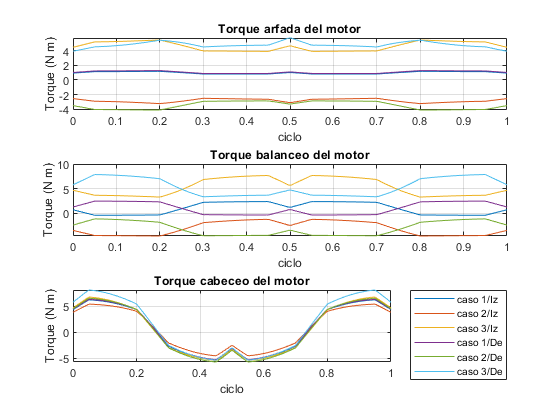

TorqueA1izM=TorqueA1iz/N;
TorqueA2izM=TorqueA2iz/N;
TorqueA3izM=TorqueA3iz/N;
TorqueC1izM=TorqueC1iz/N;
TorqueC2izM=TorqueC2iz/N;
TorqueC3izM=TorqueC3iz/N;
TorqueB1izM=TorqueB1iz/N;
TorqueB2izM=TorqueB2iz/N;
TorqueB3izM=TorqueB3iz/N;
TorqueA1deM=TorqueA1de/N;
TorqueA2deM=TorqueA2de/N;
TorqueA3deM=TorqueA3de/N;
TorqueC1deM=TorqueC1de/N;
TorqueC2deM=TorqueC2de/N;
TorqueC3deM=TorqueC3de/N;
TorqueB1deM=TorqueB1de/N;
TorqueB2deM=TorqueB2de/N;
TorqueB3deM=TorqueB3de/N;



figure()
subplot(3,1,1)
plot(linspace(0,1,160),TorqueA1izM)
hold on
plot(linspace(0,1,160),TorqueA2izM)
plot(linspace(0,1,160),TorqueA3izM)
plot(linspace(0,1,160),TorqueA1deM)
plot(linspace(0,1,160),TorqueA2deM)
plot(linspace(0,1,160),TorqueA3deM)
hold off
%legend("caso 1/Iz","caso 2/Iz","caso 3/Iz","caso 1/De","caso 2/De","caso 3/De","Location","bestoutside")
title("Torque arfada del motor")
ylabel("Torque (N m)")
xlabel("ciclo")
grid on
subplot(3,1,2)
plot(linspace(0,1,160),TorqueB1izM)
hold on
plot(linspace(0,1,160),TorqueB2izM)
plot(linspace(0,1,160),TorqueB3izM)
plot(linspace(0,1,160),TorqueB1deM)
plot(linspace(0,1,160),TorqueB2deM)
plot(linspace(0,1,160),TorqueB3deM)
hold off
%legend("caso 1/Iz","caso 2/Iz","caso 3/Iz","caso 1/De","caso 2/De","caso 3/De","Location","bestoutside")
title("Torque balanceo del motor")
ylabel("Torque (N m)")
xlabel("ciclo")
grid on
subplot(3,1,3)
plot(linspace(0,1,160),TorqueC1izM)
hold on
plot(linspace(0,1,160),TorqueC2izM)
plot(linspace(0,1,160),TorqueC3izM)
plot(linspace(0,1,160),TorqueC1deM)
plot(linspace(0,1,160),TorqueC2deM)
plot(linspace(0,1,160),TorqueC3deM)
hold off
legend("caso 1/Iz","caso 2/Iz","caso 3/Iz","caso 1/De","caso 2/De","caso 3/De","Location","bestoutside")
title("Torque cabeceo del motor")
ylabel("Torque (N m)")
xlabel("ciclo")
grid on



TRMSA1izM=rms(TorqueA1izM);
TRMSA2izM=rms(TorqueA2izM);
TRMSA3izM=rms(TorqueA3izM);
TRMSC1izM=rms(TorqueC1izM);
TRMSC2izM=rms(TorqueC2izM);
TRMSC3izM=rms(TorqueC3izM);
TRMSB1izM=rms(TorqueB1izM);
TRMSB2izM=rms(TorqueB2izM);
TRMSB3izM=rms(TorqueB3izM);
TRMSA1deM=rms(TorqueA1deM);
TRMSA2deM=rms(TorqueA2deM);
TRMSA3deM=rms(TorqueA3deM);
TRMSC1deM=rms(TorqueC1deM);
TRMSC2deM=rms(TorqueC2deM);
TRMSC3deM=rms(TorqueC3deM);
TRMSB1deM=rms(TorqueB1deM);
TRMSB2deM=rms(TorqueB2deM);
TRMSB3deM=rms(TorqueB3deM);


MatrizTorque=abs([TorqueA1izM,TorqueA2izM,TorqueA3izM,TorqueC1izM,TorqueC2izM,TorqueC3izM,TorqueB1izM,TorqueB2izM,TorqueB3izM,TorqueA1deM,TorqueA2deM,TorqueA3deM,TorqueC1deM,TorqueC2deM,TorqueC3deM,TorqueB1deM,TorqueB2deM,TorqueB3deM]);

ArregloMaxTorque=max(MatrizTorque);
TorqueMax=max(ArregloMaxTorque)

TorqueMax = 8.1103

ArregloTRMS=[TRMSA1izM,TRMSA2izM,TRMSA3izM,TRMSC1izM,TRMSC2izM,TRMSC3izM,TRMSB1izM,TRMSB2izM,TRMSB3izM,TRMSA1deM,TRMSA2deM,TRMSA3deM,TRMSC1deM,TRMSC2deM,TRMSC3deM,TRMSB1deM,TRMSB2deM,TRMSB3deM];
TorqueRMSMax=max(ArregloTRMS)

TorqueRMSMax = 5.6908

### Velocidad motor

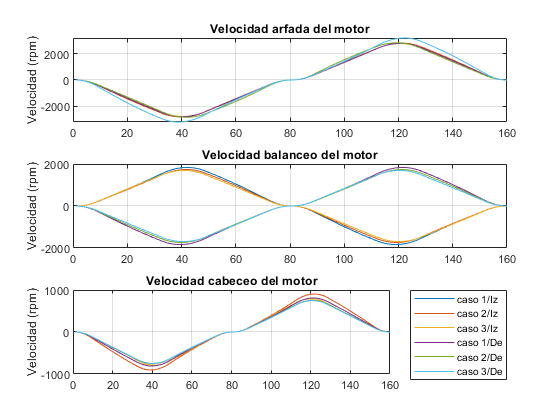


velocidadMA1iz=velocidadA1iz*N;
velocidadMA2iz=velocidadA2iz*N;
velocidadMA3iz=velocidadA3iz*N;
velocidadMC1iz=velocidadC1iz*N;
velocidadMC2iz=velocidadC2iz*N;
velocidadMC3iz=velocidadC3iz*N;
velocidadMB1iz=velocidadB1iz*N;
velocidadMB2iz=velocidadB2iz*N;
velocidadMB3iz=velocidadB3iz*N;
velocidadMA1de=velocidadA1de*N;
velocidadMA2de=velocidadA2de*N;
velocidadMA3de=velocidadA3de*N;
velocidadMC1de=velocidadC1de*N;
velocidadMC2de=velocidadC2de*N;
velocidadMC3de=velocidadC3de*N;
velocidadMB1de=velocidadB1de*N;
velocidadMB2de=velocidadB2de*N;
velocidadMB3de=velocidadB3de*N;


figure()
subplot(3,1,1)
plot(velocidadMA1iz*30/pi)
hold on
plot(velocidadMA2iz*30/pi)
plot(velocidadMA3iz*30/pi)
plot(velocidadMA1de*30/pi)
plot(velocidadMA2de*30/pi)
plot(velocidadMA3de*30/pi)
hold off
%legend("caso 1/Iz","caso 2/Iz","caso 3/Iz","caso 1/De","caso 2/De","caso 3/De","Location","bestoutside")
title("Velocidad arfada del motor")
ylabel("Velocidad (rpm)")
grid on
subplot(3,1,2)
plot(velocidadMB1iz*30/pi)
hold on
plot(velocidadMB2iz*30/pi)
plot(velocidadMB3iz*30/pi)
plot(velocidadMB1de*30/pi)
plot(velocidadMB2de*30/pi)
plot(velocidadMB3de*30/pi)
hold off
%legend("caso 1/Iz","caso 2/Iz","caso 3/Iz","caso 1/De","caso 2/De","caso 3/De","Location","bestoutside")
title("Velocidad balanceo del motor")
ylabel("Velocidad (rpm)")
grid on
subplot(3,1,3)
plot(velocidadMC1iz*30/pi)
hold on
plot(velocidadMC2iz*30/pi)
plot(velocidadMC3iz*30/pi)
plot(velocidadMC1de*30/pi)
plot(velocidadMC2de*30/pi)
plot(velocidadMC3de*30/pi)
hold off
legend("caso 1/Iz","caso 2/Iz","caso 3/Iz","caso 1/De","caso 2/De","caso 3/De","Location","bestoutside")
title("Velocidad cabeceo del motor")
ylabel("Velocidad (rpm)")
grid on

### Potencia motor

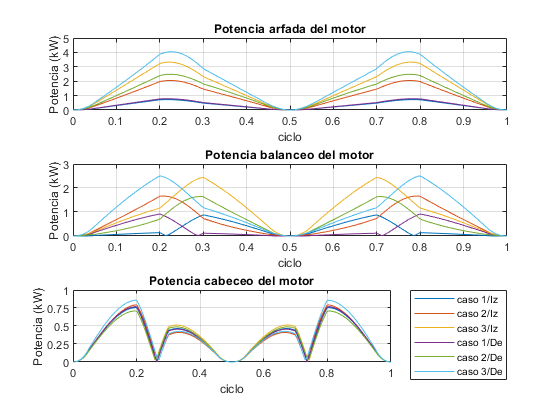


PotenciaMA1iz=PotenciaA1iz/EficienciaReductor;
PotenciaMA2iz=PotenciaA2iz/EficienciaReductor;
PotenciaMA3iz=PotenciaA3iz/EficienciaReductor;
PotenciaMC1iz=PotenciaC1iz/EficienciaReductor;
PotenciaMC2iz=PotenciaC2iz/EficienciaReductor;
PotenciaMC3iz=PotenciaC3iz/EficienciaReductor;
PotenciaMB1iz=PotenciaB1iz/EficienciaReductor;
PotenciaMB2iz=PotenciaB2iz/EficienciaReductor;
PotenciaMB3iz=PotenciaB3iz/EficienciaReductor;

PotenciaMA1de=PotenciaA1de/EficienciaReductor;
PotenciaMA2de=PotenciaA2de/EficienciaReductor;
PotenciaMA3de=PotenciaA3de/EficienciaReductor;
PotenciaMC1de=PotenciaC1de/EficienciaReductor;
PotenciaMC2de=PotenciaC2de/EficienciaReductor;
PotenciaMC3de=PotenciaC3de/EficienciaReductor;
PotenciaMB1de=PotenciaB1de/EficienciaReductor;
PotenciaMB2de=PotenciaB2de/EficienciaReductor;
PotenciaMB3de=PotenciaB3de/EficienciaReductor;


figure()
subplot(3,1,1)
plot(linspace(0,1,160),PotenciaMA1iz/1000)
hold on
plot(linspace(0,1,160),PotenciaMA2iz/1000)
plot(linspace(0,1,160),PotenciaMA3iz/1000)
plot(linspace(0,1,160),PotenciaMA1de/1000)
plot(linspace(0,1,160),PotenciaMA2de/1000)
plot(linspace(0,1,160),PotenciaMA3de/1000)
hold off
%legend("caso 1/Iz","caso 2/Iz","caso 3/Iz","caso 1/De","caso 2/De","caso 3/De","Location","bestoutside")
title("Potencia arfada del motor")
yticks(0:5)
ylabel("Potencia (kW)")
xlabel("ciclo")
grid on


subplot(3,1,2)
plot(linspace(0,1,160),PotenciaMB1iz/1000)
hold on
plot(linspace(0,1,160),PotenciaMB2iz/1000)
plot(linspace(0,1,160),PotenciaMB3iz/1000)
plot(linspace(0,1,160),PotenciaMB1de/1000)
plot(linspace(0,1,160),PotenciaMB2de/1000)
plot(linspace(0,1,160),PotenciaMB3de/1000)
hold off
%legend("caso 1/Iz","caso 2/Iz","caso 3/Iz","caso 1/De","caso 2/De","caso 3/De","Location","bestoutside")
title("Potencia balanceo del motor")
ylabel("Potencia (kW)")
ylim([0 3])
yticks(0:3)
xlabel("ciclo")
grid on


subplot(3,1,3)
plot(linspace(0,1,160),PotenciaMC1iz/1000)
hold on
plot(linspace(0,1,160),PotenciaMC2iz/1000)
plot(linspace(0,1,160),PotenciaMC3iz/1000)
plot(linspace(0,1,160),PotenciaMC1de/1000)
plot(linspace(0,1,160),PotenciaMC2de/1000)
plot(linspace(0,1,160),PotenciaMC3de/1000)
hold off

legend("caso 1/Iz","caso 2/Iz","caso 3/Iz","caso 1/De","caso 2/De","caso 3/De","Location","bestoutside")
title("Potencia cabeceo del motor")
ylabel("Potencia (kW)")
yticks(0:0.25:1)
xlabel("ciclo")
grid on

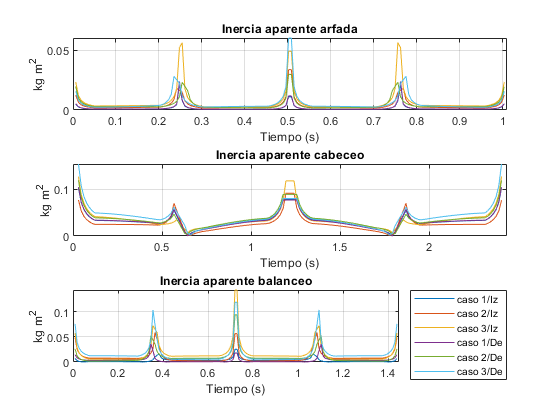





figure()
subplot(3,1,1)
plot(TA1iz,IncerciaAparenteA1iz/(N^2),TA2iz,IncerciaAparenteA2iz/(N^2),TA3iz,IncerciaAparenteA3iz/(N^2),TA1de,IncerciaAparenteA1de/(N^2),TA2de,IncerciaAparenteA2de/(N^2),TA3de,IncerciaAparenteA3de/(N^2))
title("Inercia aparente arfada")
xlim([0 double(tMax_a)])
xlabel("Tiempo (s)")
ylabel("kg m^2")
%legend("caso 1/Iz","caso 2/Iz","caso 3/Iz","caso 1/De","caso 2/De","caso 3/De","Location","northeast")
grid on

subplot(3,1,2)
plot(TC1iz,IncerciaAparenteC1iz/(N^2),TC2iz,IncerciaAparenteC2iz/(N^2),TC3iz,IncerciaAparenteC3iz/(N^2),TC1de,IncerciaAparenteC1de/(N^2),TC2de,IncerciaAparenteC2de/(N^2),TC3de,IncerciaAparenteC3de/(N^2))
title("Inercia aparente cabeceo")
xlim([0 double(tMax_c)])
xlabel("Tiempo (s)")
ylabel("kg m^2")
%legend("caso 1/Iz","caso 2/Iz","caso 3/Iz","caso 1/De","caso 2/De","caso 3/De","Location","northeast")
grid on

subplot(3,1,3)
plot(TB1iz,IncerciaAparenteB1iz/(N^2),TB2iz,IncerciaAparenteB2iz/(N^2),TB3iz,IncerciaAparenteB3iz/(N^2),TB1de,IncerciaAparenteB1de/(N^2),TB2de,IncerciaAparenteB2de/(N^2),TB3de,IncerciaAparenteB3de/(N^2))
title("Inercia aparente balanceo")
xlim([0 double(tMax_b)])
xlabel("Tiempo (s)")
ylabel("kg m^2")
legend("caso 1/Iz","caso 2/Iz","caso 3/Iz","caso 1/De","caso 2/De","caso 3/De","Location","bestoutside")
grid on

## Selección 

Imot=0.016

Imot = 0.0160

PotenciaMot=7460

PotenciaMot = 7460

FSMotor=1.15

FSMotor = 1.1500

IMot=28   %220V

IMot = 28

IarrMot=6*IMot

IarrMot = 168

EficienciaMot=0.79

EficienciaMot = 0.7900

FPMot=0.9

FPMot = 0.9000

Vnom=3500 %rpm

Vnom = 3500

TnomMot=20.35

TnomMot = 20.3500

TarrMot=2.3*TnomMot

TarrMot = 46.8050

TparMot=3.5*TnomMot

TparMot = 71.2250

### Relación de inercia

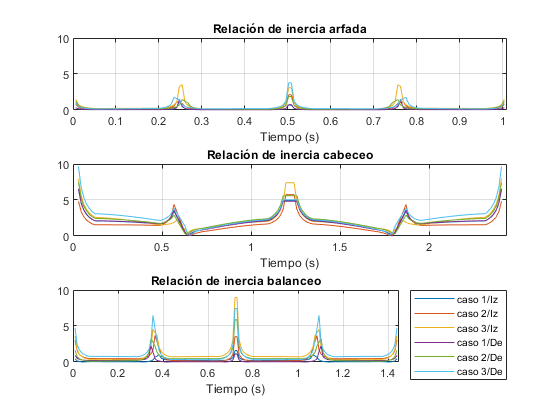

figure()
subplot(3,1,1)


plot(TA1iz,IncerciaAparenteA1iz/(N^2*Imot),TA2iz,IncerciaAparenteA2iz/(N^2*Imot),TA3iz,IncerciaAparenteA3iz/(N^2*Imot),TA1de,IncerciaAparenteA1de/(N^2*Imot),TA2de,IncerciaAparenteA2de/(N^2*Imot),TA3de,IncerciaAparenteA3de/(N^2*Imot))
title("Relación de inercia arfada")
xlim([0 double(tMax_a)])
ylim([0 10])
xlabel("Tiempo (s)")
%legend("caso 1/Iz","caso 2/Iz","caso 3/Iz","caso 1/De","caso 2/De","caso 3/De","Location","northeast")
grid on


subplot(3,1,2)
plot(TC1iz,IncerciaAparenteC1iz/(N^2*Imot),TC2iz,IncerciaAparenteC2iz/(N^2*Imot),TC3iz,IncerciaAparenteC3iz/(N^2*Imot),TC1de,IncerciaAparenteC1de/(N^2*Imot),TC2de,IncerciaAparenteC2de/(N^2*Imot),TC3de,IncerciaAparenteC3de/(N^2*Imot))
title("Relación de inercia cabeceo")
xlim([0 double(tMax_c)])
ylim([0 10])
xlabel("Tiempo (s)")
%legend("caso 1/Iz","caso 2/Iz","caso 3/Iz","caso 1/De","caso 2/De","caso 3/De","Location","northeast")
grid on

subplot(3,1,3)
plot(TB1iz,IncerciaAparenteB1iz/(N^2*Imot),TB2iz,IncerciaAparenteB2iz/(N^2*Imot),TB3iz,IncerciaAparenteB3iz/(N^2*Imot),TB1de,IncerciaAparenteB1de/(N^2*Imot),TB2de,IncerciaAparenteB2de/(N^2*Imot),TB3de,IncerciaAparenteB3de/(N^2*Imot))
title("Relación de inercia balanceo")
xlim([0 double(tMax_b)])
ylim([0 10])
xlabel("Tiempo (s)")
legend("caso 1/Iz","caso 2/Iz","caso 3/Iz","caso 1/De","caso 2/De","caso 3/De","Location","bestoutside")
grid on